# Analyze Earthquakes

Explore earthquake data from the USGS web API: [http://earthquake.usgs.gov/earthquakes/search/](http://earthquake.usgs.gov/earthquakes/search/)

## Read earthquake data

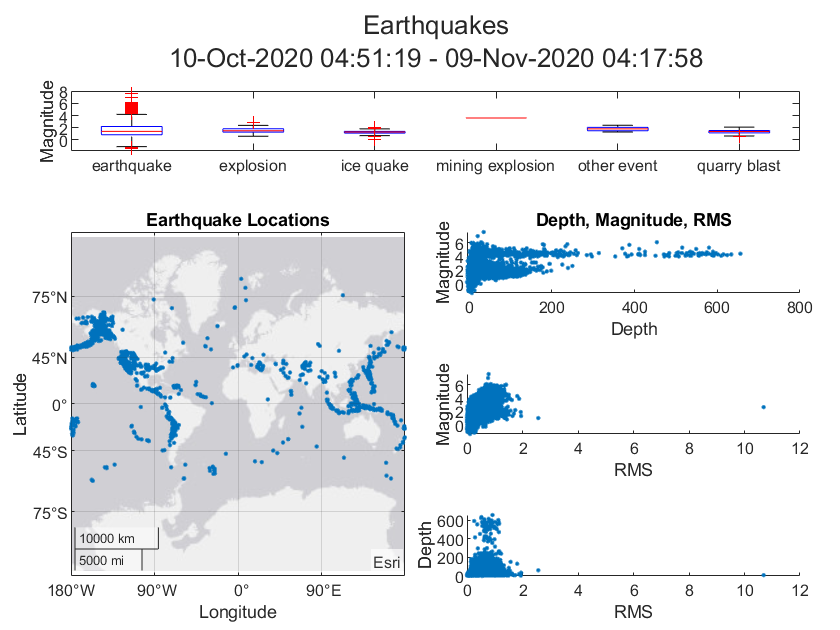

recentQuakeData = true;
quakes0 = ReadQuakes(recentQuakeData);

 

plotEarthquakeData(quakes0)
[tmin,tmax] = bounds(quakes0.time);
sgtitle(["Earthquakes",...
    string(tmin)+" - "+string(tmax)])

## Visualize earthquakes

Experiment with magnitude values and select plots to create. 

magvalue =1;
visualizeDensity = true;
visualizeByType = true;

Select data by magnitude and plot earthquakes.

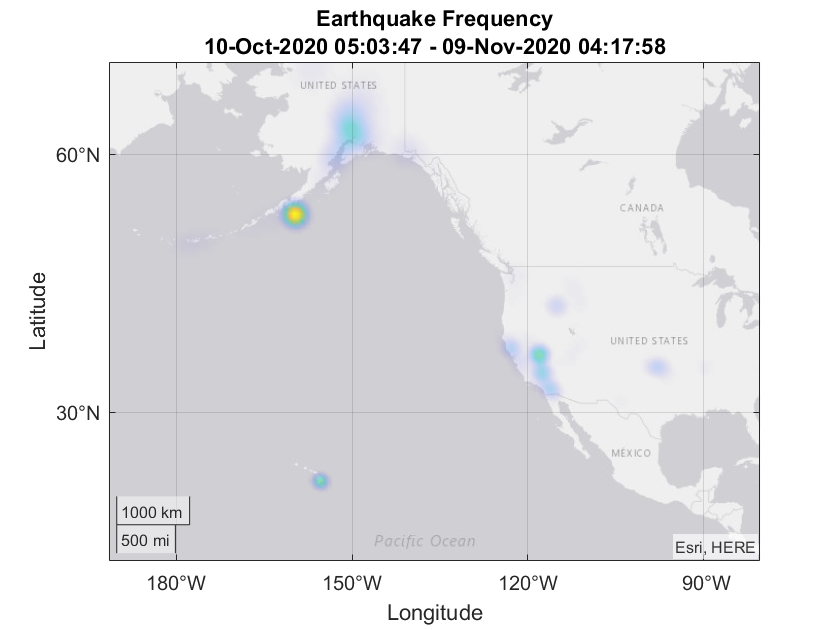

quakes = quakes0(quakes0.mag > magvalue,:);
quakes.type = removecats(quakes.type);
[tmin,tmax] = bounds(quakes.time);

if visualizeDensity
    figure
    geodensityplot(quakes.latitude,quakes.longitude,"FaceColor","interp");
    title(["Earthquake Frequency",...
        string(tmin)+" - "+string(tmax)])
    geolimits([6.1 67.0],[-189.9 -82.0])
end

if visualizeByType
    figure
    geobubble(quakes,"latitude","longitude","SizeVariable","mag",...

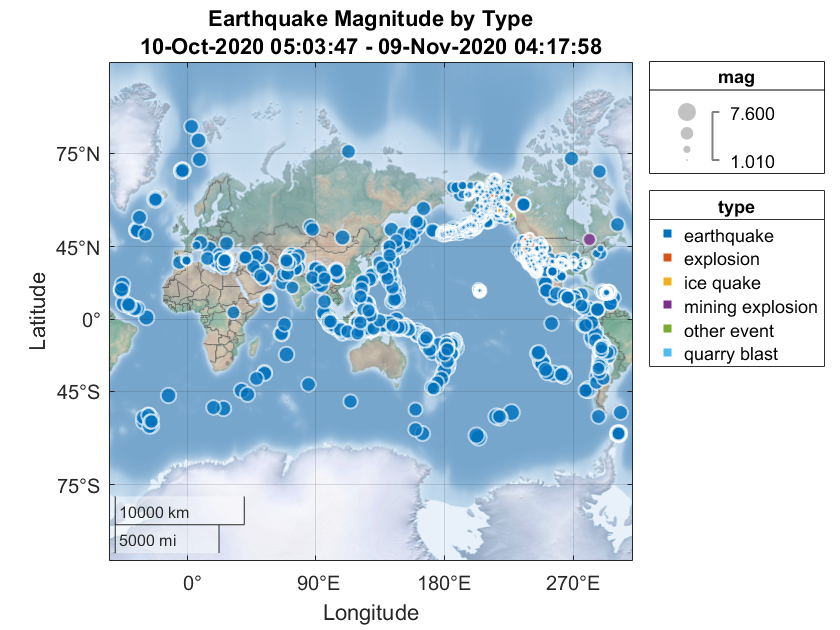

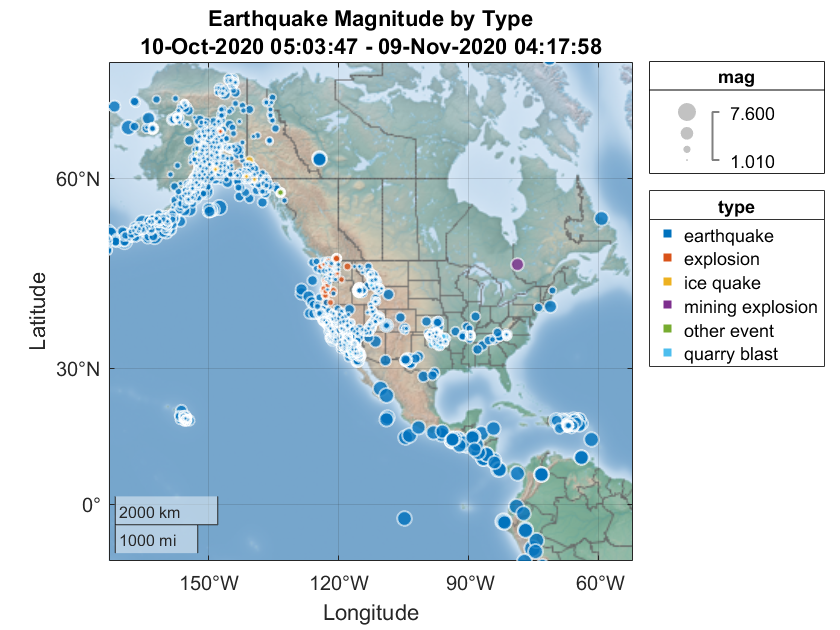

        "ColorVariable","type","Basemap","colorterrain",...
        "BubbleWidthRange",[2 10]);
    title(["Earthquake Magnitude by Type",...
        string(tmin)+" - "+string(tmax)])
% Hello: 
    typeQuakes = groupsummary(quakes,"type","max","mag");
    maxTypes = max(typeQuakes.max_mag(typeQuakes.type ~= "earthquake"));
    if length(typeQuakes.type) > 1 && magvalue <= maxTypes
        figure
        geobubble(quakes,"latitude","longitude","SizeVariable","mag",...
            "ColorVariable","type","Basemap","colorterrain",...
            "BubbleWidthRange",[2 10]);
        title(["Earthquake Magnitude by Type",...
            string(tmin)+" - "+string(tmax)])    
        geolimits([-13 71],[-172.9 -52.1])
    end
end

Visualize earthquake frequency with a wordcloud.

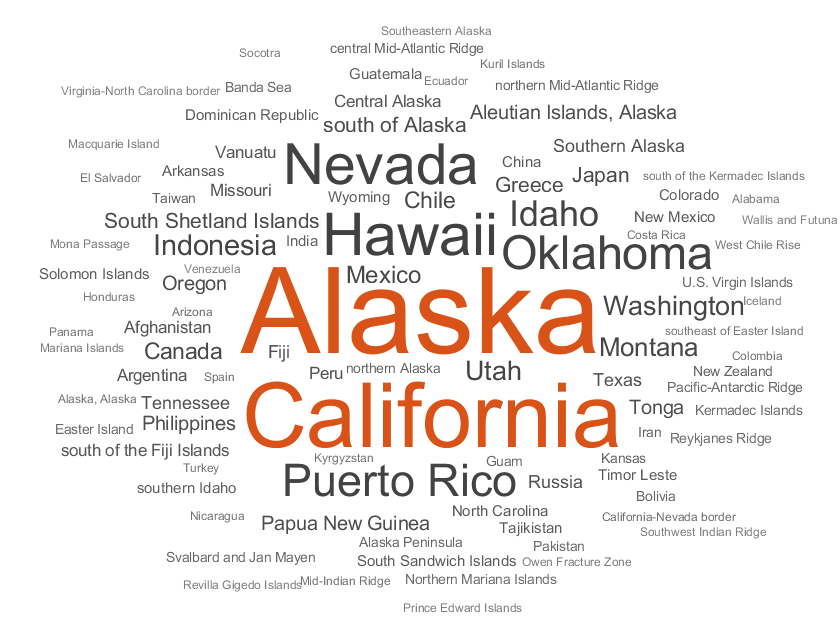

figure
wordcloud(quakes.Loc);

Display locations with the most frequent and highest magnitudes.

mnByLoc = groupsummary(quakes,"Loc","mean","mag");
topLoc = topkrows(mnByLoc,50,"GroupCount");
topFrequency = topLoc(1:10,:)

topFrequency = 10×3 table
        Loc        GroupCount    mean_mag
    ___________    __________    ________
    Alaska            3017        2.1279 
    California        1621        1.5288 
    Hawaii             630        2.0042 
    Nevada             593        1.5007 
    Oklahoma           365        1.5023 
    Puerto Rico        330        2.6058 
    Idaho              187        2.1603 
    Indonesia           93        4.6054 
    Utah                91        1.5849 
    Washington          79        1.5244 

topMagnitudes = topkrows(mnByLoc,10,"mean_mag")

topMagnitudes = 10×3 table
                Loc                GroupCount    mean_mag
    ___________________________    __________    ________
    Jan Mayen Island                   1             5.6 
    Easter Island                      5            5.26 
    Pacific-Antarctic Ridge            6            5.25 
    Uzbekistan                         1             5.2 
    West Chile Rise                    3               5 
    northern Mid-Atlantic Ridge        7          4.9286 
    Iceland                            2             4.9 
    Turkmenistan                       1             4.9 
    south of Africa                    1             4.9 
    southern Mid-Atlantic Ridge        1             4.9 

**Helper functions**

function plotEarthquakeData(quakes)
warning("off","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
figure
tiledlayout(4,2,"TileSpacing","compact","Padding","compact");
nexttile([1 2])
boxplot(quakes.mag,quakes.type)
ylabel("Magnitude")
nexttile(3,[3 1])
geoscatter(quakes.latitude,quakes.longitude,"Marker",".")
title("Earthquake Locations")
nexttile
scatter(quakes.depth,quakes.mag,".");
xlabel("Depth"); ylabel("Magnitude")
title("Depth, Magnitude, RMS")
nexttile
scatter(quakes.rms,quakes.mag,".");
xlabel("RMS"); ylabel("Magnitude")
nexttile
scatter(quakes.rms,quakes.depth,".");
xlabel("RMS"); ylabel("Depth")
warning("on","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
end